## Week 10

### Data Access - Part 1

I'd like to start off this week by talking about ways of obtaining data files online. In the last class, we briefly touched on this. I am mostly talking about obtaining data files that various agencies store online. There is great variability in this, in terms of file formats, and (current topic) the mode of accessing those data files.

So, let's first talk about FTP (file transfer protocol) access vs HTTPS access. FTP is not as common as it once was, but some government agencies still use it. HTTPS is more secure, and easier to use. So, we will focus on a demonstration of this. For this example we will consider SNODAS model data.

clear all
close all
clc

web('https://noaadata.apps.nsidc.org/NOAA/G02158/masked/2023/04_Apr/')

The above command, on a mac will open up a browser

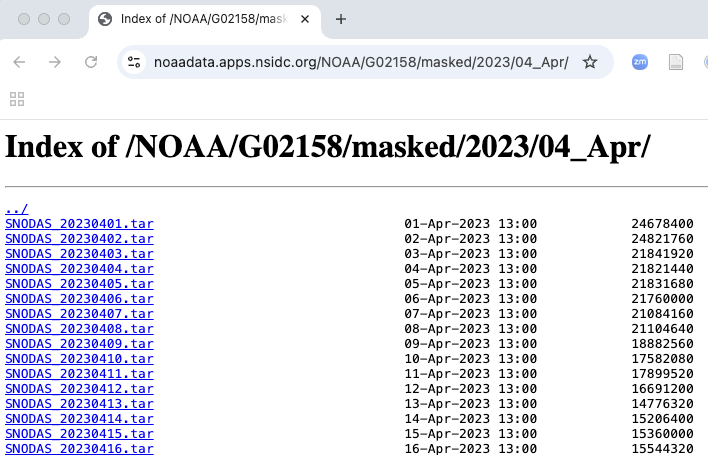

Here, we see a listing of compressed archives (each file is around 24MB) for April 2023. If you click on any one of these in the browser window, it will download. So, this is fine. You can click around in NOAA's HTTPS site, find the files you want, and then download them. 

However, this process is kind of tedious. It would be really nice to be able to write some code to automate tasks associated with finding and downloading data. Especially in cases where the data archive is dynamic (adding new files each eay, month, or year) and you would like to go grab 'updates' or newly added files. See the simple loop below as a way to go to a directory at a HTTPS site and pull down all of the data files there.

baseurl='https://noaadata.apps.nsidc.org/NOAA/G02158/masked/2023/04_Apr/';

%use loop over 30 days of april
for j=1:30
    filename=['SNODAS_202304' sprintf('%02d', j) '.tar'];
    websave(filename,[baseurl,filename]);
end

If you take a look at things with a directory listing now:

ls *.tar

SNODAS_20230401.tar	SNODAS_20230402.tar	SNODAS_20230403.tar	SNODAS_20230404.tar	SNODAS_20230405.tar	SNODAS_20230406.tar	SNODAS_20230407.tar	SNODAS_20230408.tar	SNODAS_20230409.tar	SNODAS_20230410.tar	SNODAS_20230411.tar	SNODAS_20230412.tar	SNODAS_20230413.tar	SNODAS_20230414.tar	SNODAS_20230415.tar	SNODAS_20230416.tar	SNODAS_20230417.tar	SNODAS_20230418.tar	SNODAS_20230419.tar	SNODAS_20230420.tar	SNODAS_20230421.tar	SNODAS_20230422.tar	SNODAS_20230423.tar	SNODAS_20230424.tar	SNODAS_20230425.tar	SNODAS_20230426.tar	SNODAS_20230427.tar	SNODAS_20230428.tar	SNODAS_20230429.tar	SNODAS_20230430.tar



By the way, if you are not familiar, a 'tar' file is essentially an archive, or a collection of individual files. We can unpack a tar file with something like this

untar('SNODAS_20230401.tar','test')

This will store the output of this unpacking into a directory called 'test'. If you now go look at that directory, you will see a bunch of *.gz files. These are essentially zip files (compressed files), which you can unzip using the gunzip command.

So, it's that easy. Automating tasks this way will save you a lot of clicks when you have a TON of data files to download. Note: I am now going to delete all of these files just to clean up our directory. I will also delete the 'test' directory. 

delete *.tar
cd test
delete *.*
cd ..
rmdir test